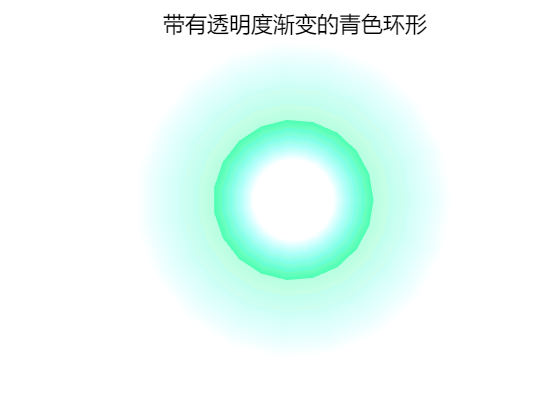

% 参数设置
num_points = 20; % 圆的点数
r_inner = 0.5; % 内圆半径
r_outer = 1; % 外圆半径

% 生成圆的坐标
theta = linspace(0, 2*pi, num_points);
x_inner = r_inner * cos(theta);
y_inner = r_inner * sin(theta);
x_outer = r_outer * cos(theta);
y_outer = r_outer * sin(theta);

% 合并坐标，创建环形
x = [x_outer, fliplr(x_inner)];
y = [y_outer, fliplr(y_inner)];
z = 0.05*ones(size(x));
x1 = 4*x + ego.pos(1);
y1 = 4*y + ego.pos(2);
x2 = 2*x + ego.pos(1);
y2 = 2*y + ego.pos(2);


% 定义颜色和透明度渐变
cdata1 = [zeros(1,num_points), ones(1, num_points)]';
cdata2 = [ones(1, num_points),zeros(1,num_points)]';
alpha_data1 = [zeros(1,num_points), 0.2*ones(1, num_points)]';
alpha_data2 = [0.5*ones(1, num_points),zeros(1,num_points)]';
% 创建figure
figure;
hold on
% 绘制环形
h1 = fill3( x1, y1,z, cdata1, 'FaceColor', 'interp', ...
    'EdgeColor', 'none', 'FaceAlpha', 'interp', 'FaceVertexAlphaData', alpha_data1);
h2 = fill3( x2, y2,z, cdata2, 'FaceColor', 'interp', ...
    'EdgeColor', 'none', 'FaceAlpha', 'interp', 'FaceVertexAlphaData', alpha_data2);



% 设置颜色映射为青色
colormap([linspace(0,0.3,5)',linspace(1,1,5)',linspace(1,0.7,5)']);

% 设置坐标轴比例
axis equal;

% 添加标题
title('带有透明度渐变的青色环形');

% 移除坐标轴
axis off;

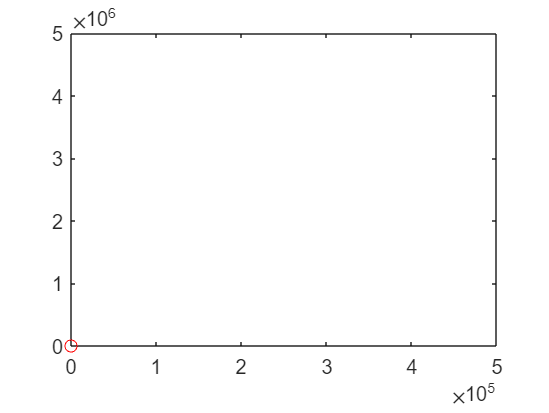



figure
plot(x1,y1,'b')
hold on 
plot(x2,y2,'b')
scatter(x(1:5),y(1:5),'r')
hold off

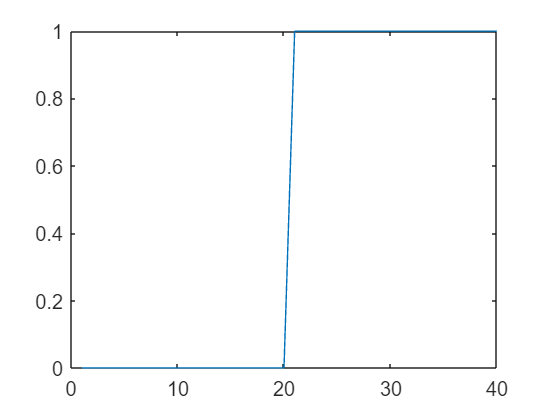


figure
plot(cdata)